# Project1 : Speech synthesis and perception

涂峻绫(12213010), 欧阳莹轩(12212961), 肖星辰(12212904), 欧阳安男(12211831)

## Introduction

## Results and Analysis

### Task 1

- Set LPF cut-off frequency to 50 Hz.

- Implement tone-vocoder by changing the number of bands to N=4, N=8, N=16, and N=32.

- Save the wave files for these conditions and describe how the number of bands affects the intelligibility (i.e., how many words can be understood) of synthesized sentence.

Initialize and load audio.

clear;clc;
[sig, fs] = audioread('proj1/C_01_02.wav');

Set LPF cut-off frequency.

cut_off = 50;

Implement tone-vocoder.

N = 4

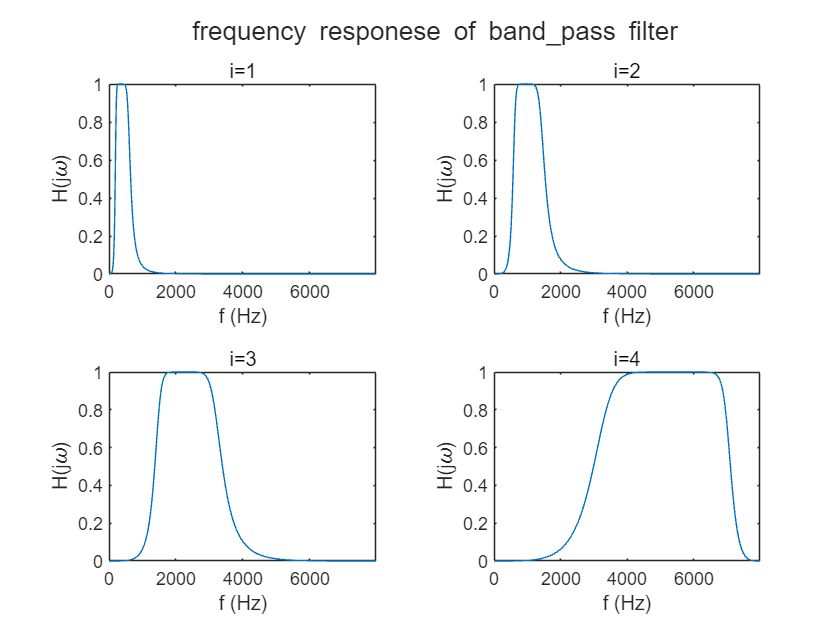

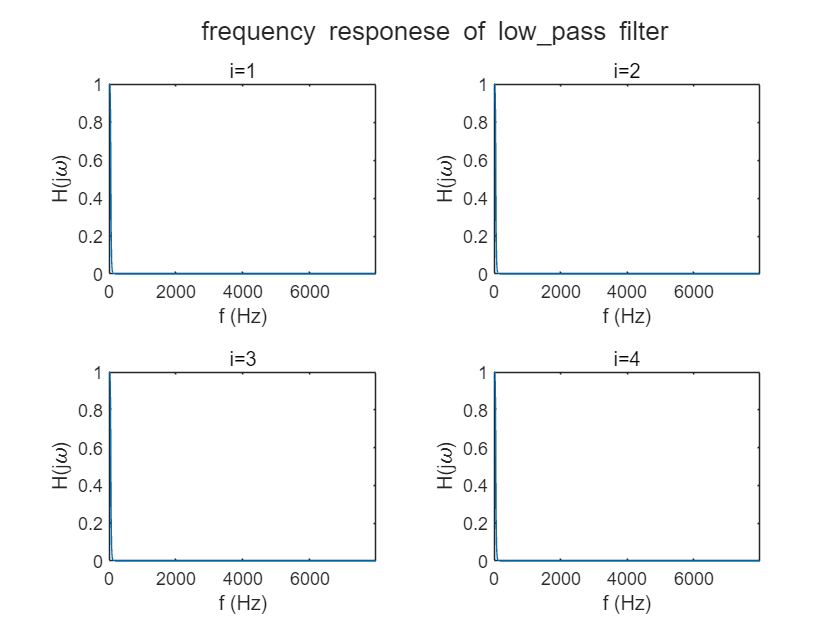

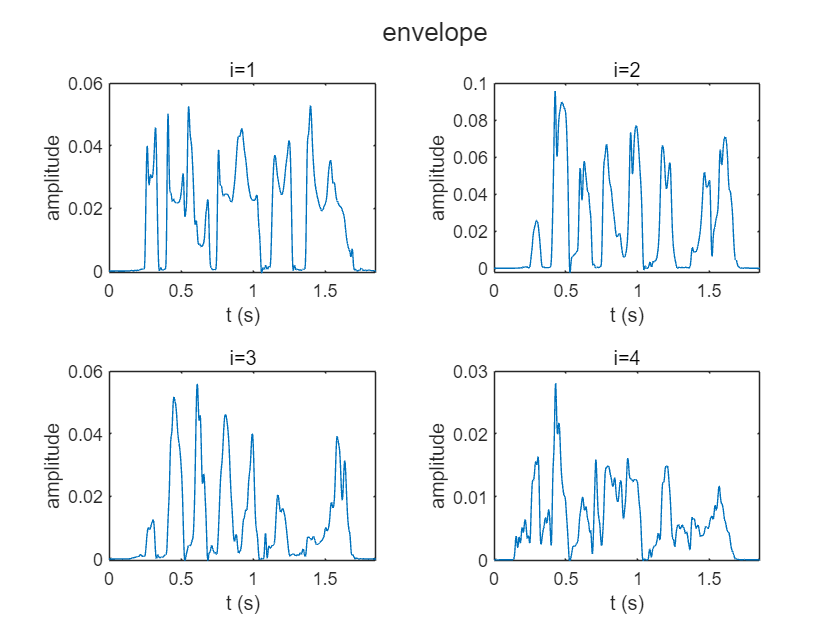

N_4 = speech_synthesis(sig, fs, 4, cut_off);

N = 8

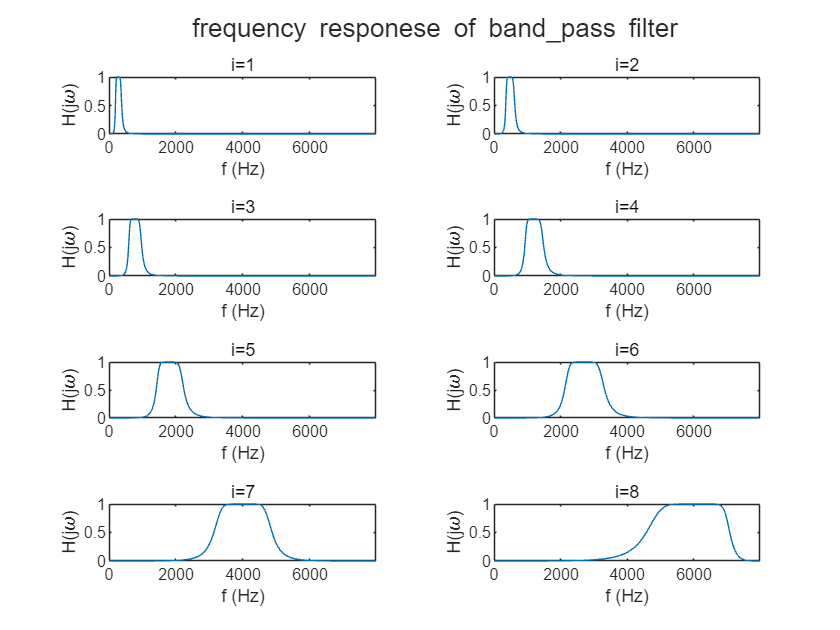

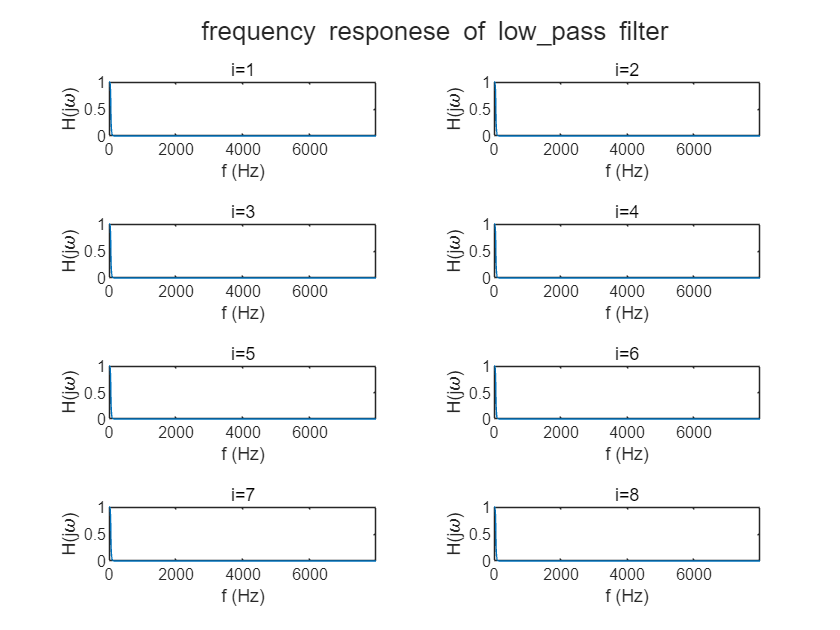

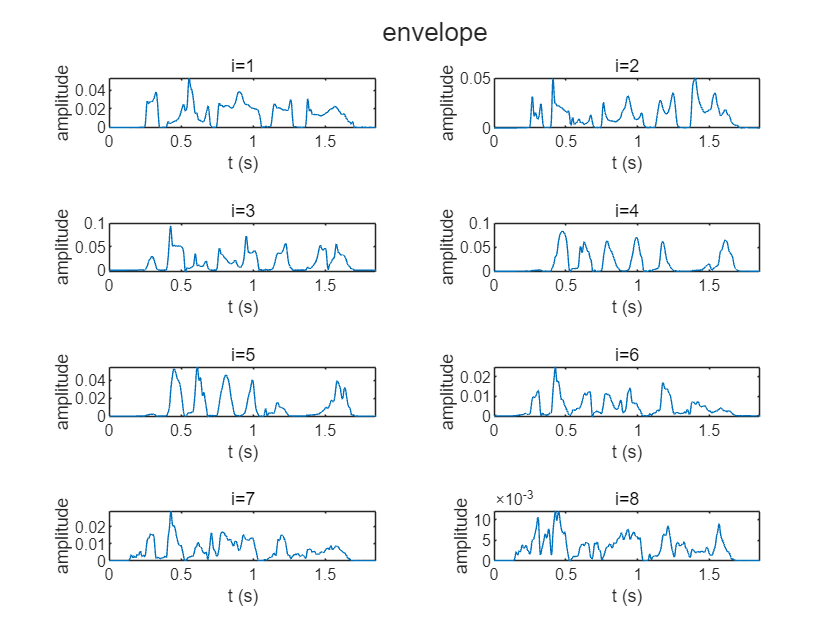

N_8 = speech_synthesis(sig, fs, 8, cut_off);

N = 16

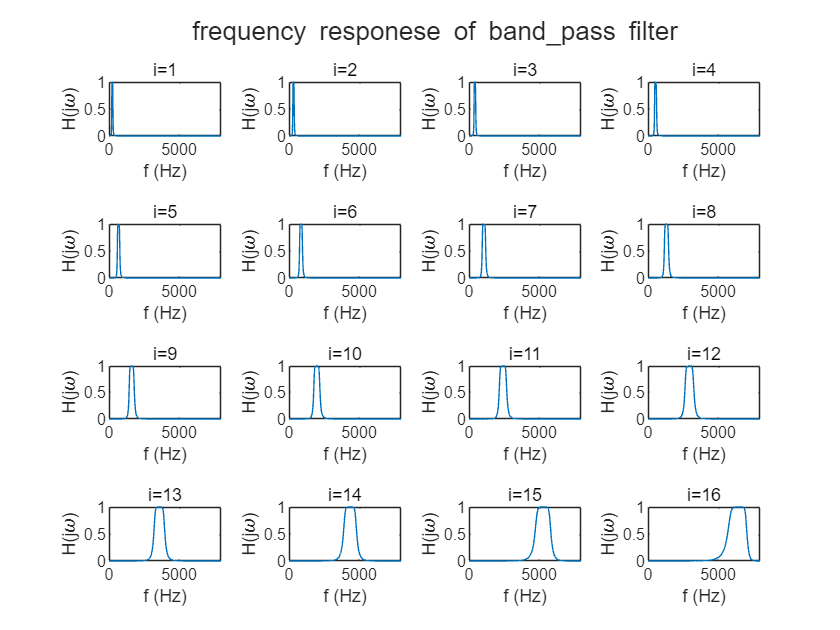

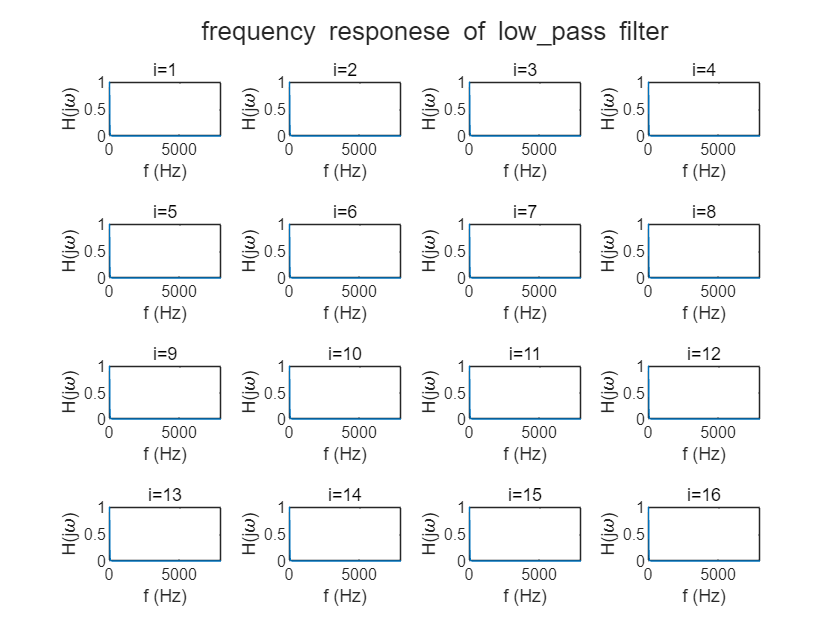

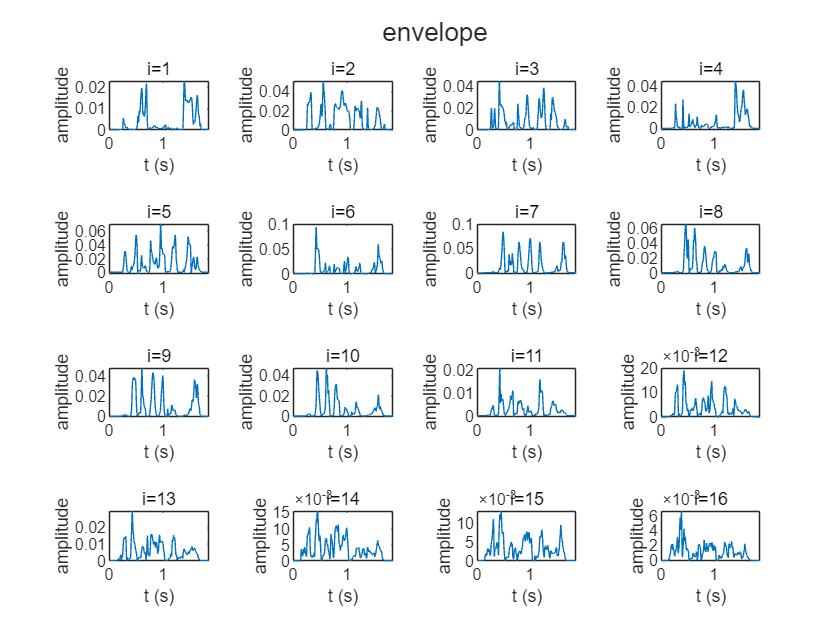

N_16 = speech_synthesis(sig, fs, 16, cut_off);

N = 32

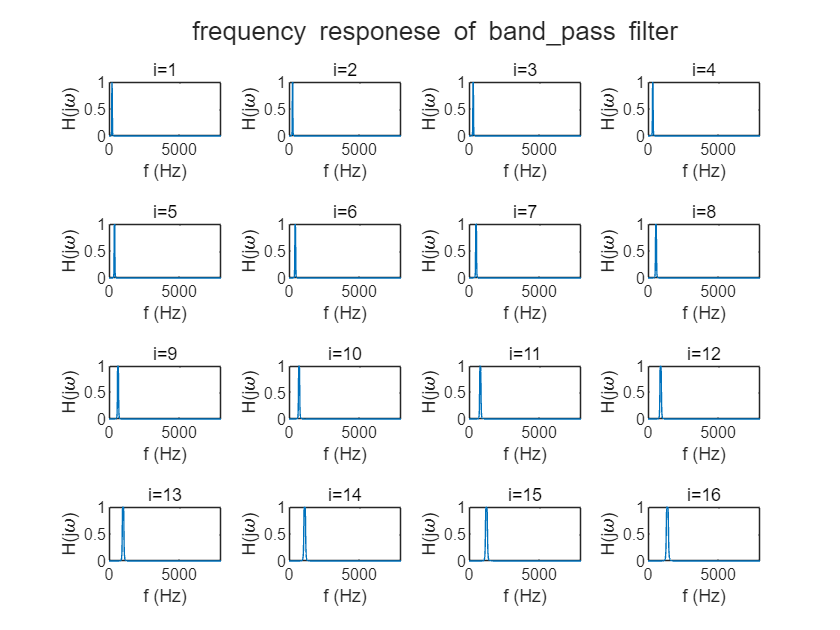

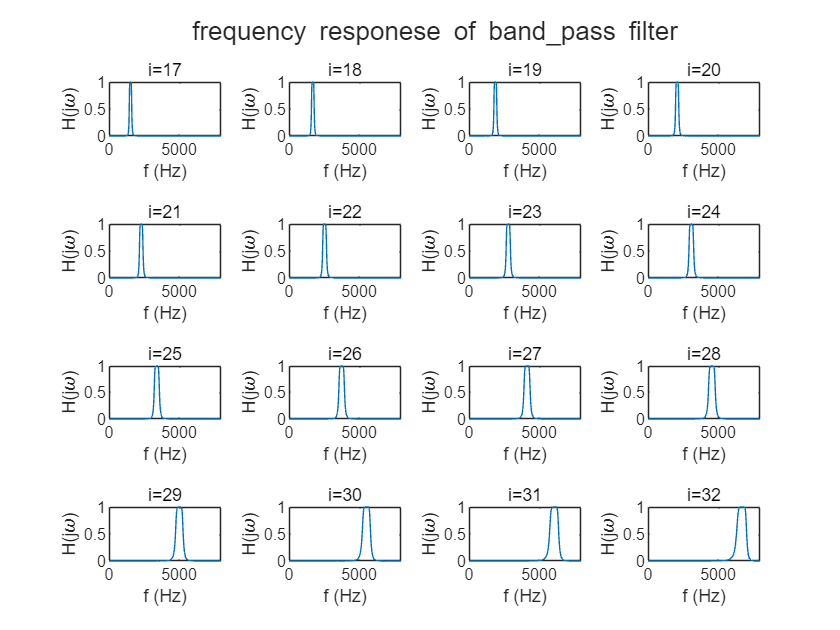

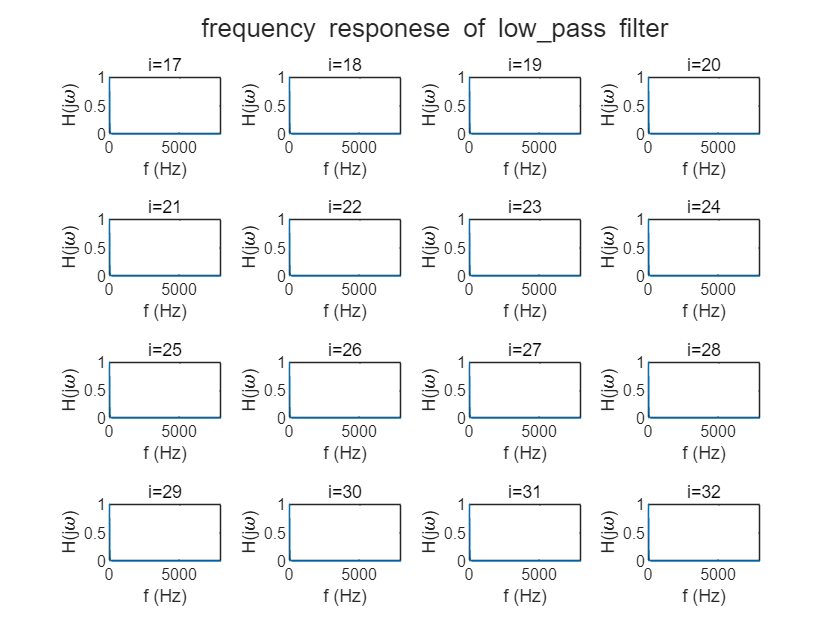

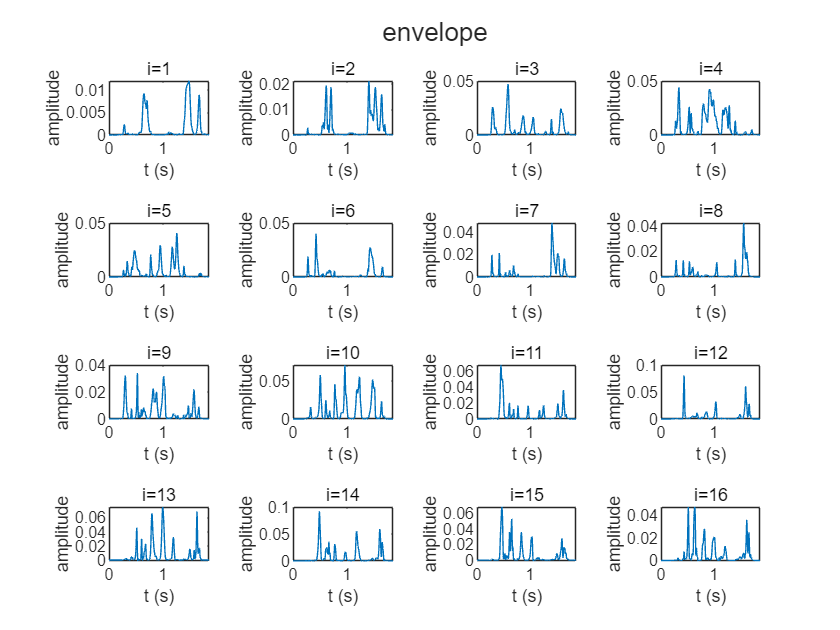

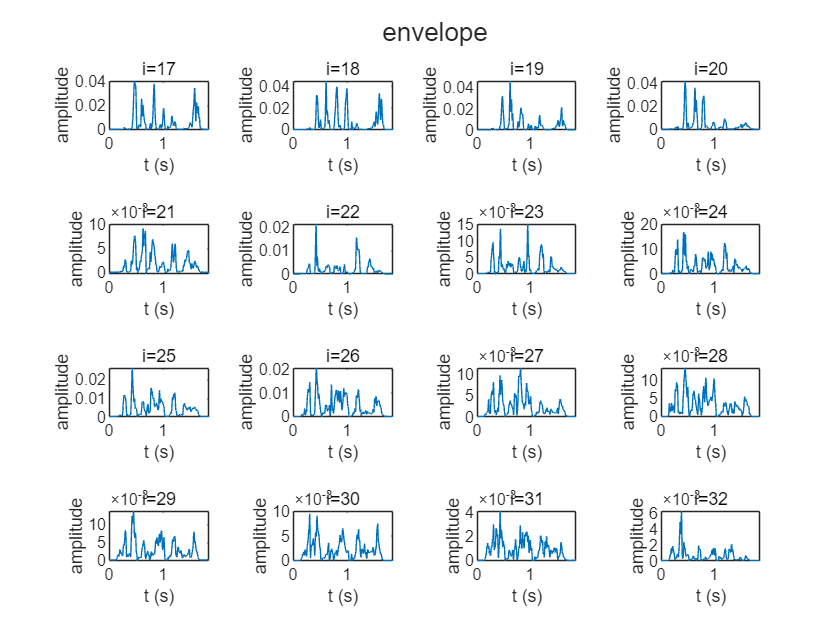

N_32 = speech_synthesis(sig, fs, 32, cut_off);

Check energy normalization.

sig_norm = norm(sig);
feq(norm(N_4), sig_norm)

ans = logical
   1


feq(norm(N_8), sig_norm)

ans = logical
   1


feq(norm(N_16), sig_norm)

ans = logical
   1


feq(norm(N_32), sig_norm)

ans = logical
   1


Plot each result.

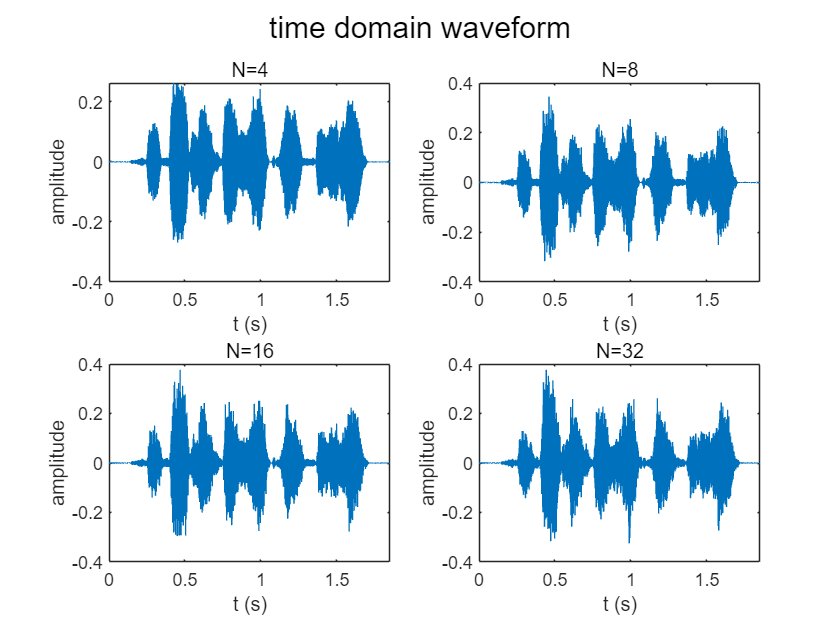

t = (0:length(sig)-1)'./fs;
figure;
sgtitle('time domain waveform');
subplot(2, 2, 1);
plot(t, N_4);
axis([t(1) t(end) ylim]);
title('N=4');
xlabel('t (s)');
ylabel('amplitude');
subplot(2, 2, 2);
plot(t, N_8);
axis([t(1) t(end) ylim]);
title('N=8');
xlabel('t (s)');
ylabel('amplitude');
subplot(2, 2, 3);
plot(t, N_16);
axis([t(1) t(end) ylim]);
title('N=16');
xlabel('t (s)');
ylabel('amplitude');
subplot(2, 2, 4);
plot(t, N_32);
axis([t(1) t(end) ylim]);
title('N=32');
xlabel('t (s)');
ylabel('amplitude');

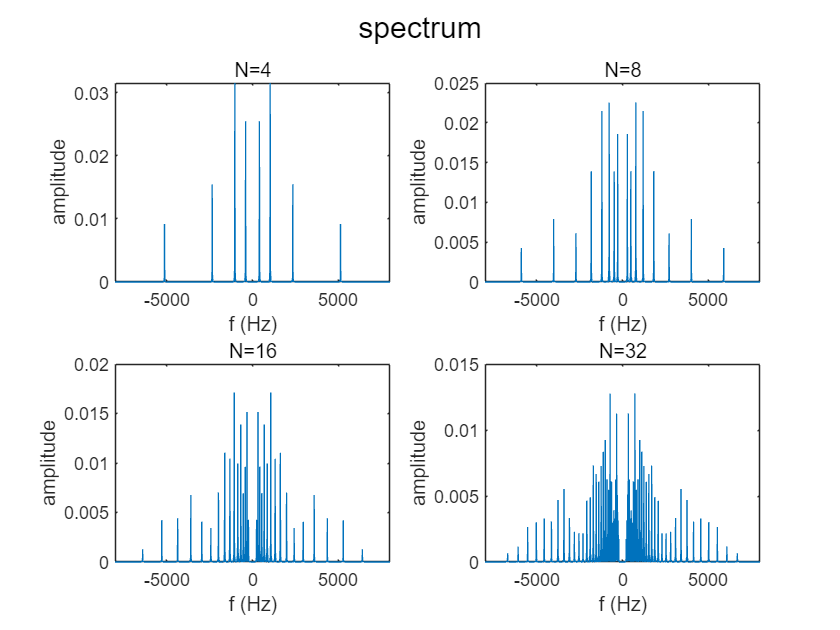


if mod(length(sig), 2) == 1
    freqency = linspace(-fs/2, fs/2, length(sig));
else
    freqency = linspace(-fs/2, fs/2, length(sig) + 1);
    freqency = freqency(1:end-1);
end
figure;
sgtitle('spectrum');
subplot(2, 2, 1);
plot(freqency, abs(fftshift(fft(N_4))/fs));
axis([freqency(1) freqency(end) ylim]);
title('N=4');
xlabel('f (Hz)');
ylabel('amplitude');
subplot(2, 2, 2);
plot(freqency, abs(fftshift(fft(N_8))/fs));
axis([freqency(1) freqency(end) ylim]);
title('N=8');
xlabel('f (Hz)');
ylabel('amplitude');
subplot(2, 2, 3);
plot(freqency, abs(fftshift(fft(N_16))/fs));
axis([freqency(1) freqency(end) ylim]);
title('N=16');
xlabel('f (Hz)');
ylabel('amplitude');
subplot(2, 2, 4);
plot(freqency, abs(fftshift(fft(N_32))/fs));
axis([freqency(1) freqency(end) ylim]);
title('N=32');
xlabel('f (Hz)');
ylabel('amplitude');

Save the processed audio.

audiowrite('proj1/T1_4_50.wav', N_4, fs);
audiowrite('proj1/T1_8_50.wav', N_8, fs);
audiowrite('proj1/T1_16_50.wav', N_16, fs);
audiowrite('proj1/T1_32_50.wav', N_32, fs);

#### Destcription

### Task 2

- Set the number of bands N=8.

- Implement tone-vocoder by changing the LPF cut-off frequency to 20 Hz, 50 Hz, 100 Hz, and 400 Hz.

- Describe how the LPF cut-off frequency affects the intelligibility of synthesized sentence.

Initialize and load audio.

clear;clc;
[sig, fs] = audioread('proj1/C_01_02.wav');

Set the number of bands.

N = 8;

Implement tone-vocoder.

cut_off = 20 (Hz)

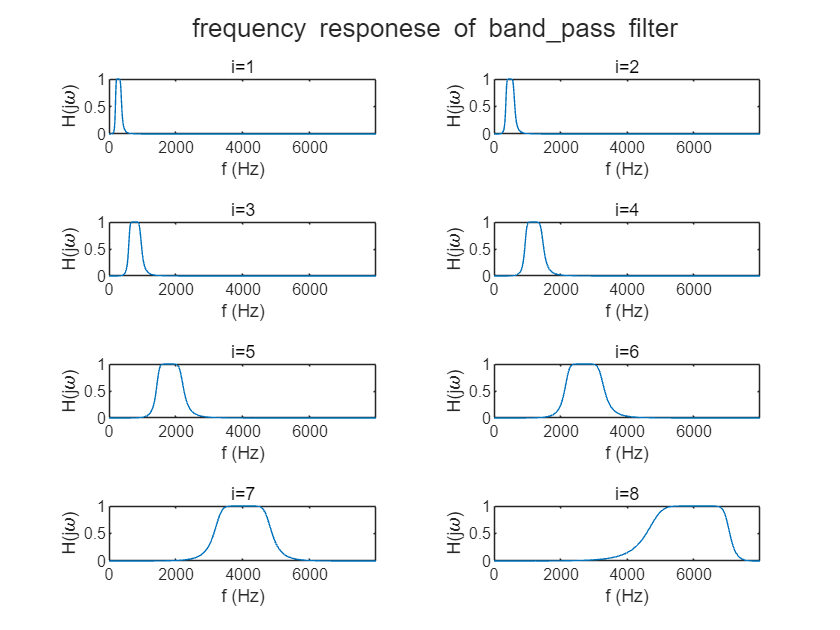

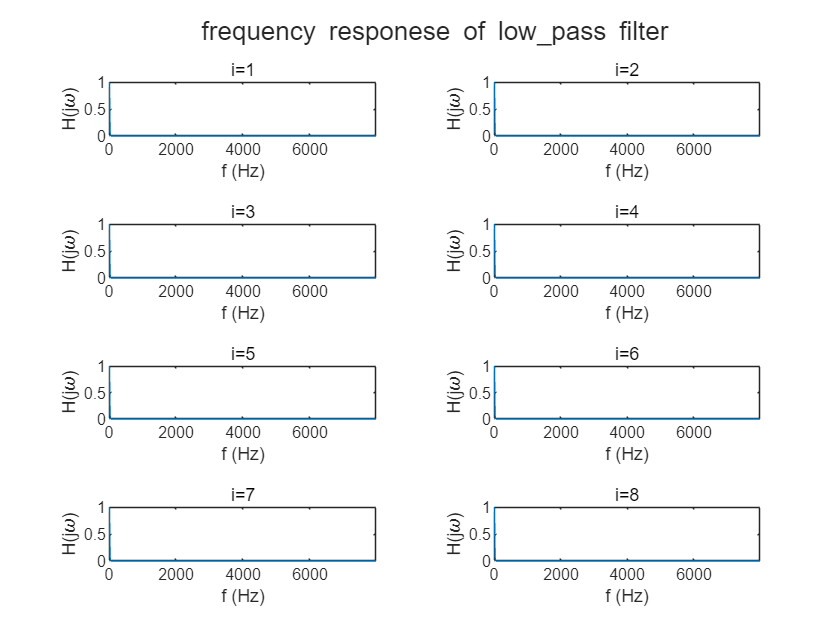

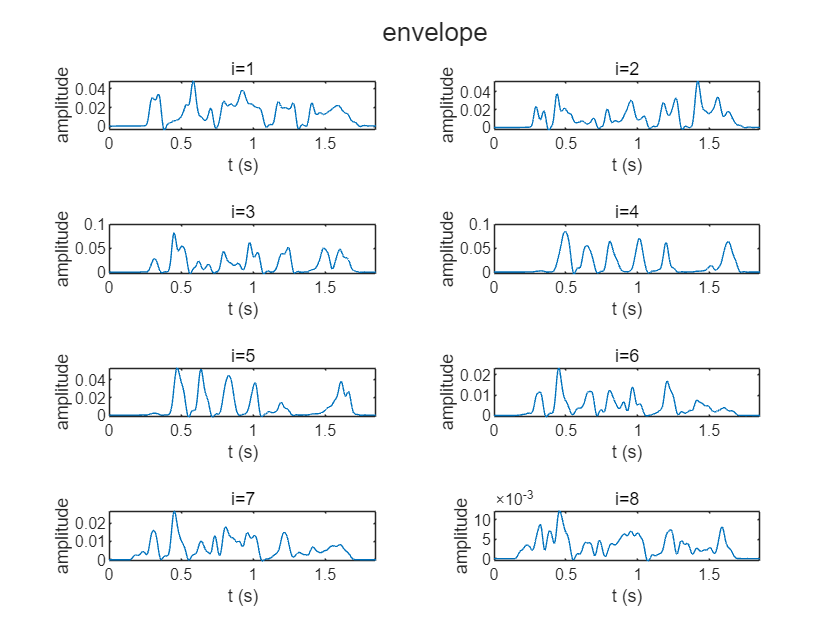

cut_off_20 = speech_synthesis(sig, fs, N, 20);

cut_off = 50 (Hz)

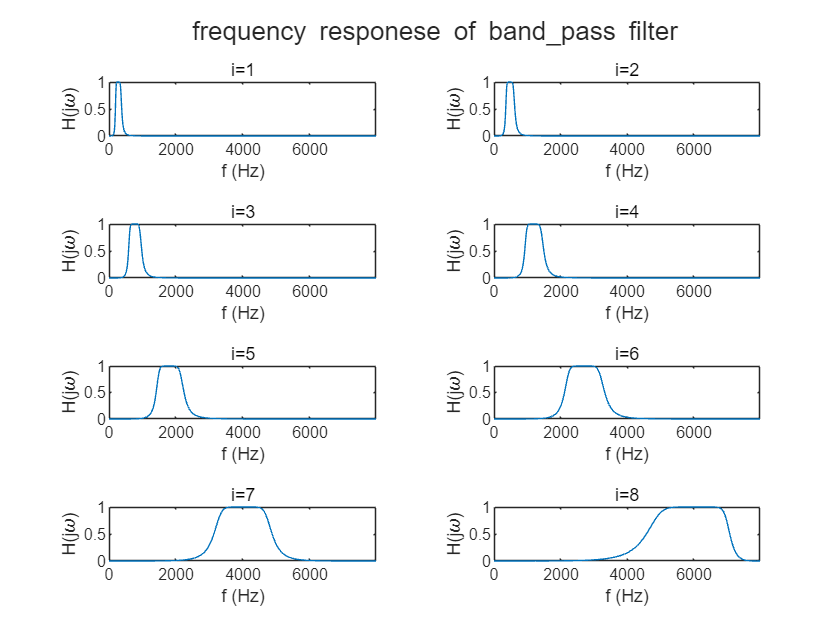

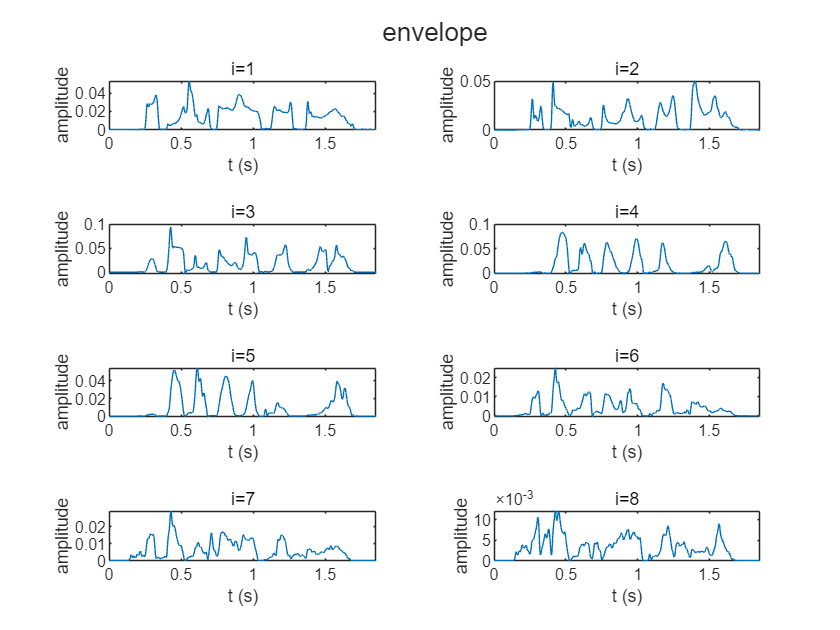

cut_off_50 = speech_synthesis(sig, fs, N, 50);

cut_off = 100 (Hz)

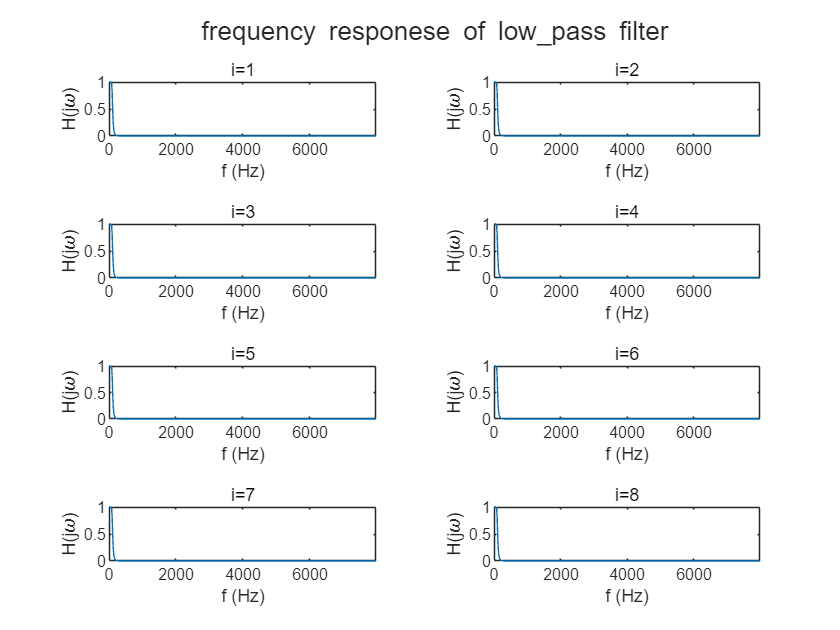

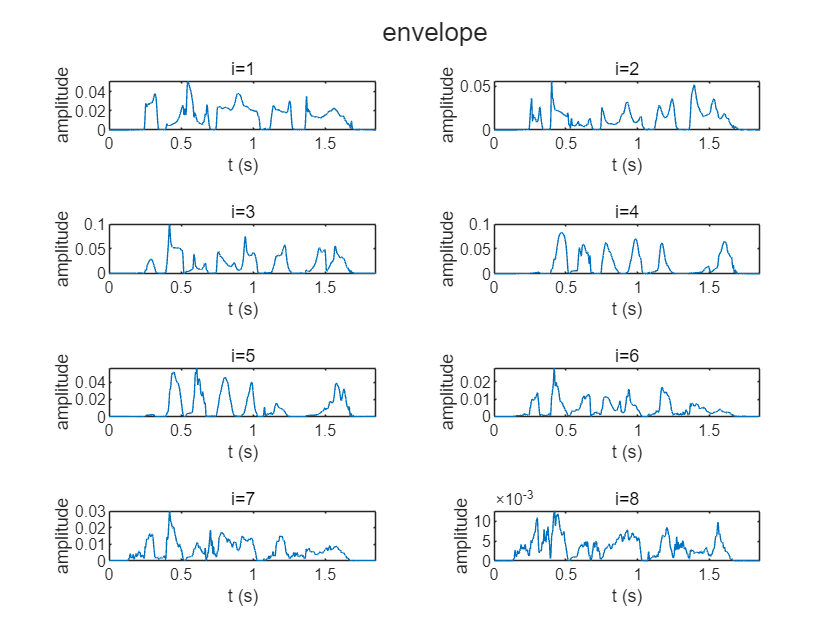

cut_off_100 = speech_synthesis(sig, fs, N, 100);

cut_off = 400 (Hz)

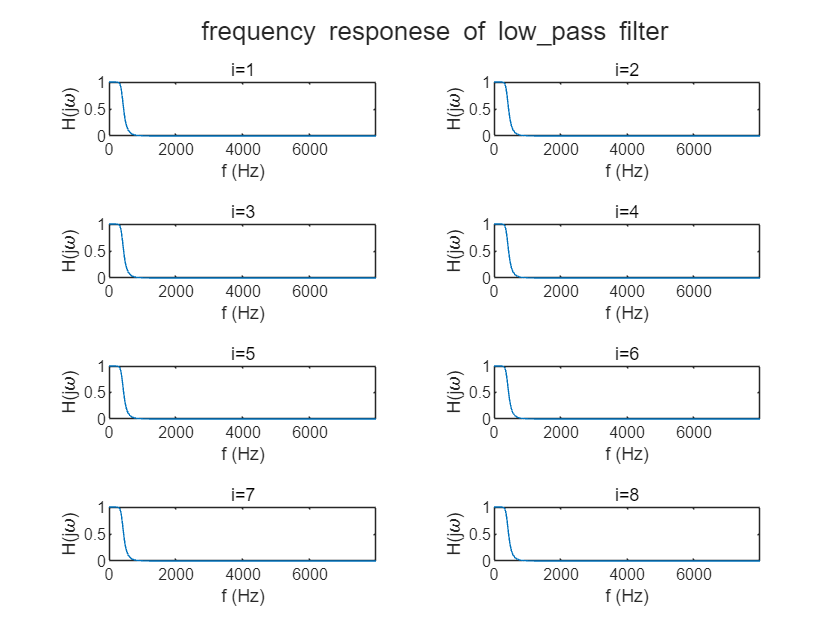

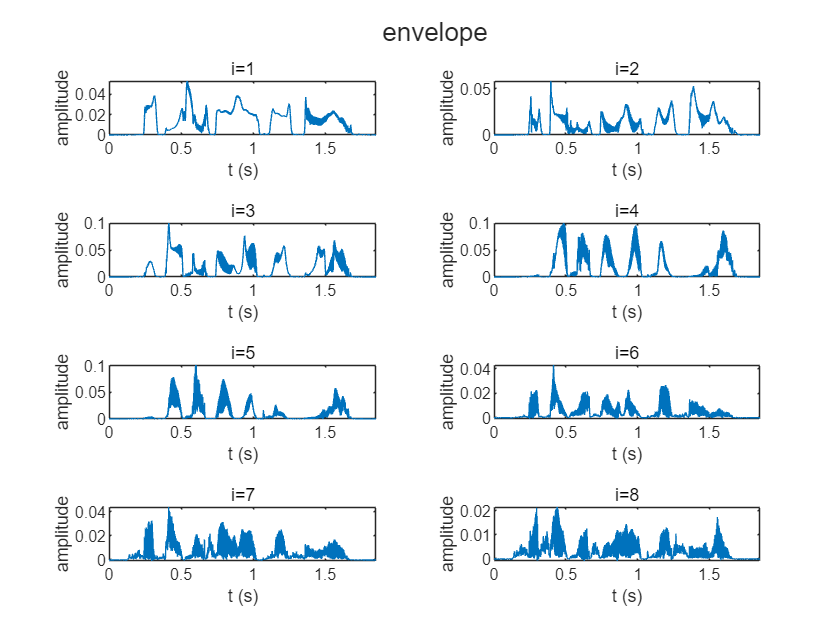

cut_off_400 = speech_synthesis(sig, fs, N, 400);

Check energy normalization.

sig_norm = norm(sig);
feq(norm(cut_off_20), sig_norm)

ans = logical
   1


feq(norm(cut_off_50), sig_norm)

ans = logical
   1


feq(norm(cut_off_100), sig_norm)

ans = logical
   1


feq(norm(cut_off_400), sig_norm)

ans = logical
   1


Plot each result.

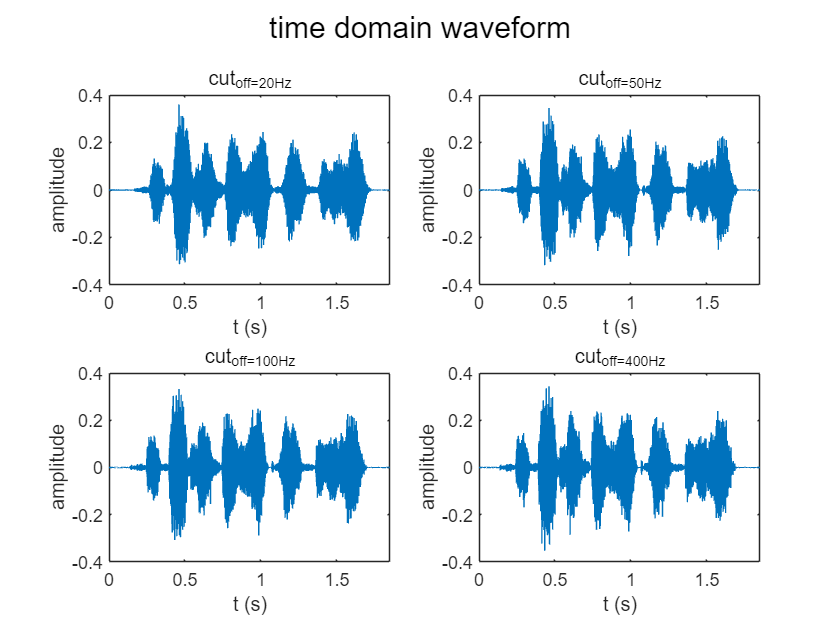

t = (0:length(sig)-1)'./fs;
figure;
sgtitle('time domain waveform');
subplot(2, 2, 1);
plot(t, cut_off_20);
axis([t(1) t(end) ylim]);
title('cut_off=20Hz');
xlabel('t (s)');
ylabel('amplitude');
subplot(2, 2, 2);
plot(t, cut_off_50);
axis([t(1) t(end) ylim]);
title('cut_off=50Hz');
xlabel('t (s)');
ylabel('amplitude');
subplot(2, 2, 3);
plot(t, cut_off_100);
axis([t(1) t(end) ylim]);
title('cut_off=100Hz');
xlabel('t (s)');
ylabel('amplitude');
subplot(2, 2, 4);
plot(t, cut_off_400);
axis([t(1) t(end) ylim]);
title('cut_off=400Hz');
xlabel('t (s)');
ylabel('amplitude');

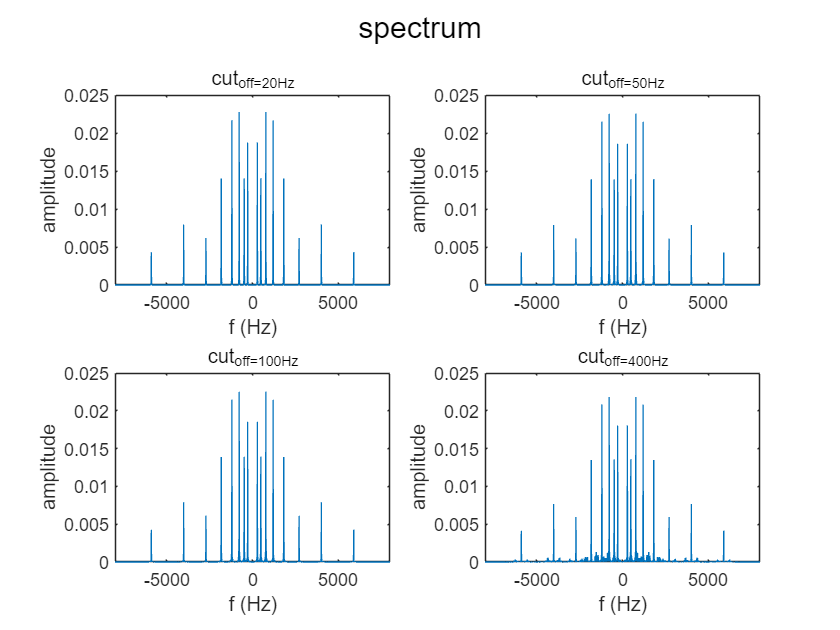


if mod(length(sig), 2) == 1
    freqency = linspace(-fs/2, fs/2, length(sig));
else
    freqency = linspace(-fs/2, fs/2, length(sig) + 1);
    freqency = freqency(1:end-1);
end
figure;
sgtitle('spectrum');
subplot(2, 2, 1);
plot(freqency, abs(fftshift(fft(cut_off_20))/fs));
axis([freqency(1) freqency(end) ylim]);
title('cut_off=20Hz');
xlabel('f (Hz)');
ylabel('amplitude');
subplot(2, 2, 2);
plot(freqency, abs(fftshift(fft(cut_off_50))/fs));
axis([freqency(1) freqency(end) ylim]);
title('cut_off=50Hz');
xlabel('f (Hz)');
ylabel('amplitude');
subplot(2, 2, 3);
plot(freqency, abs(fftshift(fft(cut_off_100))/fs));
axis([freqency(1) freqency(end) ylim]);
title('cut_off=100Hz');
xlabel('f (Hz)');
ylabel('amplitude');
subplot(2, 2, 4);
plot(freqency, abs(fftshift(fft(cut_off_400))/fs));
axis([freqency(1) freqency(end) ylim]);
title('cut_off=400Hz');
xlabel('f (Hz)');
ylabel('amplitude');

Save the processed audio.

audiowrite('proj1/T2_8_20.wav', cut_off_20, fs);
audiowrite('proj1/T2_8_50.wav', cut_off_50, fs);
audiowrite('proj1/T2_8_100.wav', cut_off_100, fs);
audiowrite('proj1/T2_8_400.wav', cut_off_400, fs);

#### Destcription

### Task 3

- Generate a noisy signal by summing the clean sentence and speech-shaped noise (SSN) at SNR -5 dB.

- Set LPF cut-off frequency to 50 Hz.

- Implement tone-vocoder by changing the number of bands to N=4, N=8, N=16, and N=32.

- Describe how the number of bands affects the intelligibility of synthesized sentence and compare findings with those obtained in task 1.

Initialize and load audio.

clear;clc;
[sig, fs] = audioread('proj1/C_01_02.wav');

Generate -5 dB SNR.

snr = sig / sqrt(10);

Generate speech-shaped noise (SSN).

ssn = get_ssn(snr, fs) .* 10^(1/4);

Generate noisy signal.

noisy_sig = sig + ssn;

 Check SNR -5 dB.

feq(20 * log10(norm(sig)/norm(ssn)), -5)

ans = logical
   1


Set LPF cut-off frequency.

cut_off = 50;

Implement tone-vocoder.

N = 4

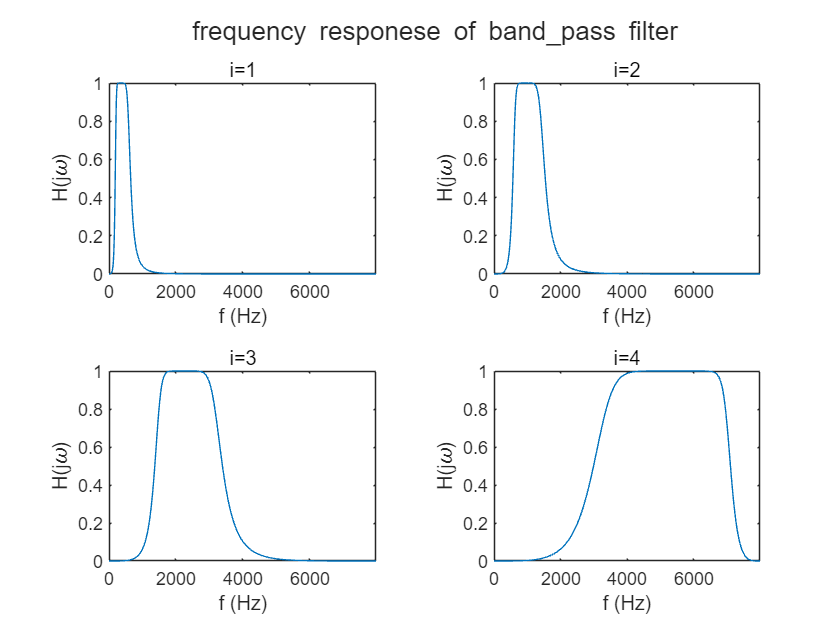

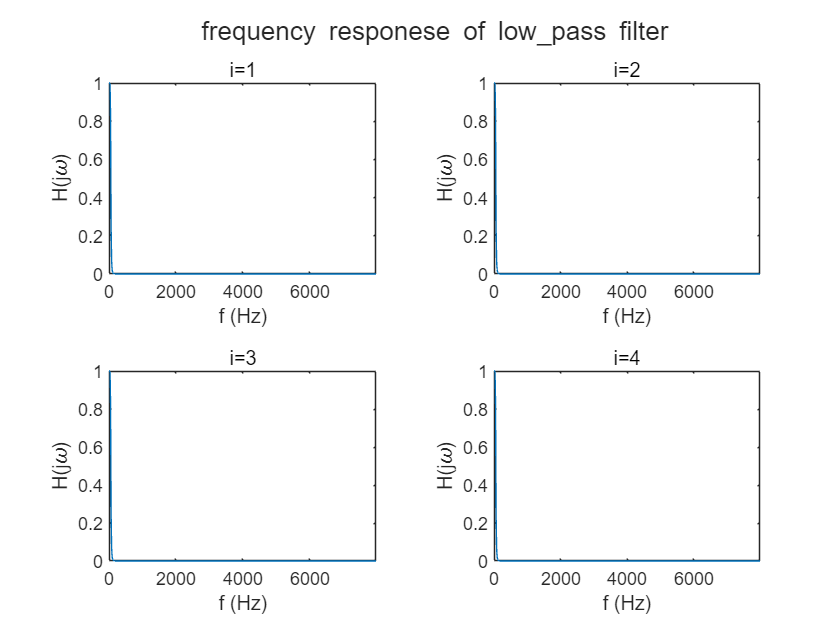

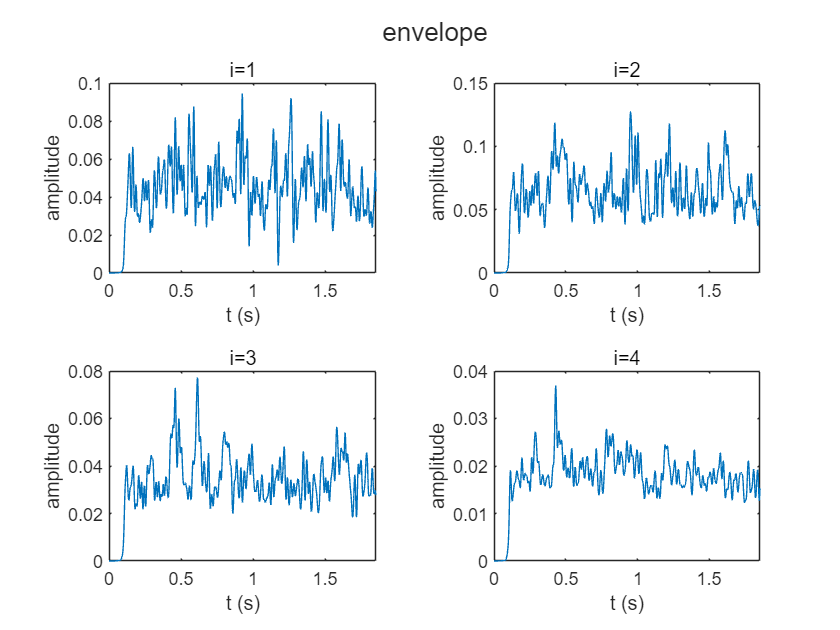

N_4 = speech_synthesis(noisy_sig, fs, 4, cut_off);

N = 8

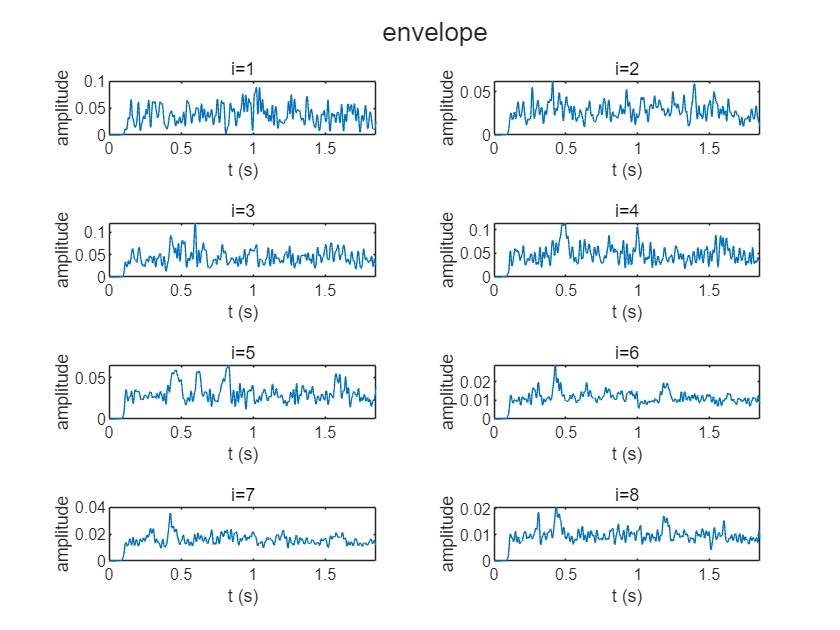

N_8 = speech_synthesis(noisy_sig, fs, 8, cut_off);

N = 16

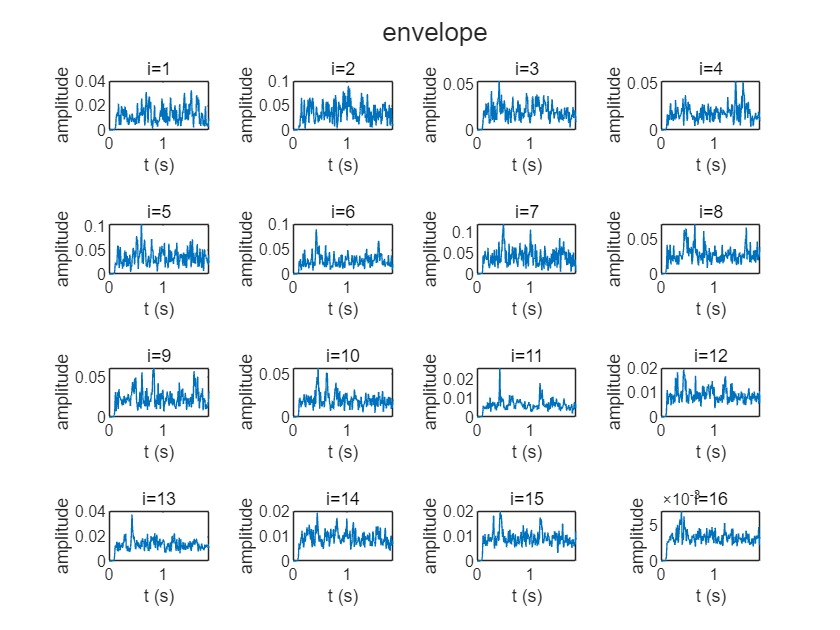

N_16 = speech_synthesis(noisy_sig, fs, 16, cut_off);

N = 32

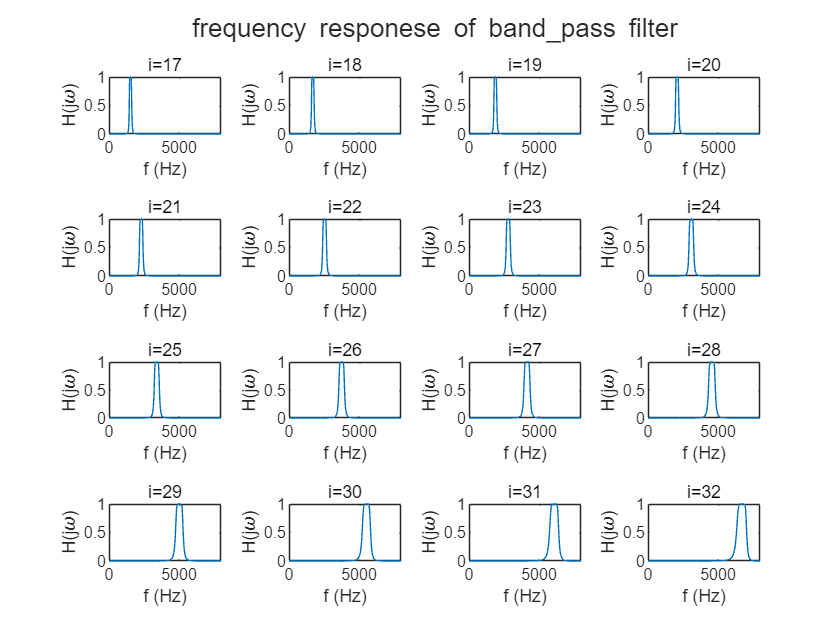

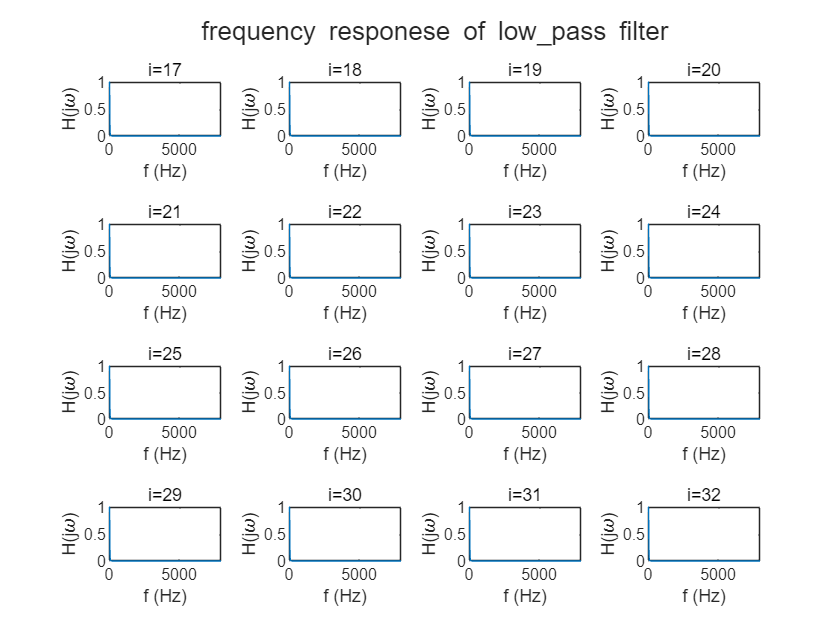

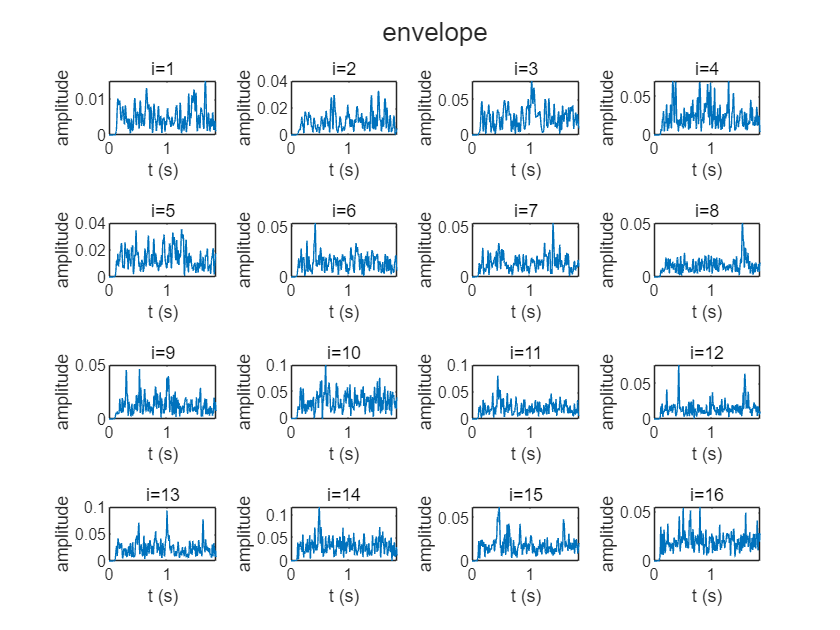

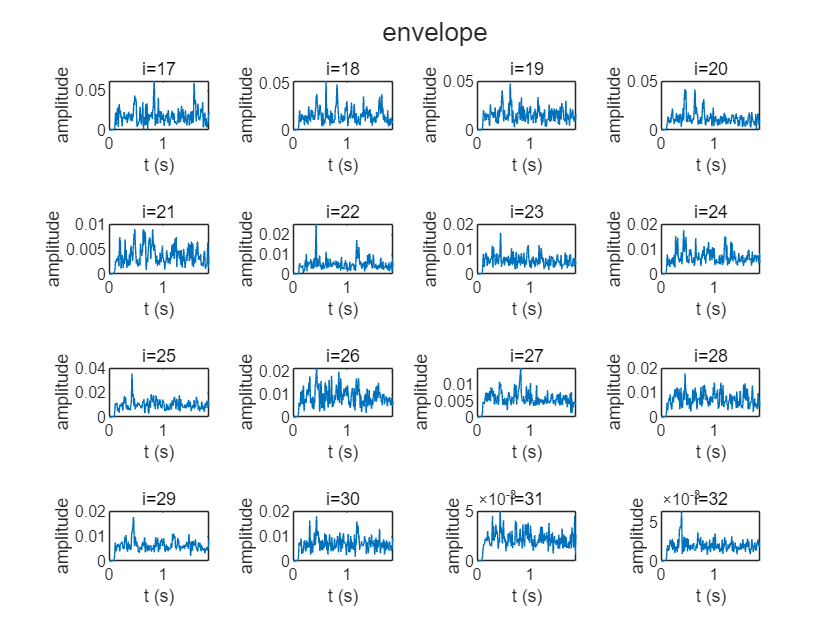

N_32 = speech_synthesis(noisy_sig, fs, 32, cut_off);

Check energy normalization.

noisy_sig_norm = norm(noisy_sig);
feq(norm(N_4), noisy_sig_norm)

ans = logical
   1


feq(norm(N_8), noisy_sig_norm)

ans = logical
   1


feq(norm(N_16), noisy_sig_norm)

ans = logical
   1


feq(norm(N_32), noisy_sig_norm)

ans = logical
   1


Plot each result.

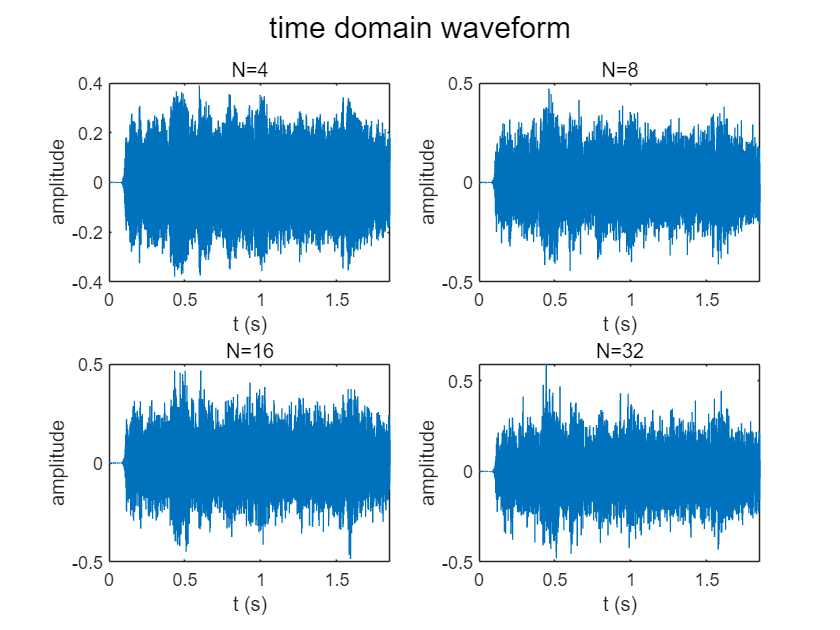

t = (0:length(sig)-1)'./fs;
figure;
sgtitle('time domain waveform');
subplot(2, 2, 1);
plot(t, N_4);
axis([t(1) t(end) ylim]);
title('N=4');
xlabel('t (s)');
ylabel('amplitude');
subplot(2, 2, 2);
plot(t, N_8);
axis([t(1) t(end) ylim]);
title('N=8');
xlabel('t (s)');
ylabel('amplitude');
subplot(2, 2, 3);
plot(t, N_16);
axis([t(1) t(end) ylim]);
title('N=16');
xlabel('t (s)');
ylabel('amplitude');
subplot(2, 2, 4);
plot(t, N_32);
axis([t(1) t(end) ylim]);
title('N=32');
xlabel('t (s)');
ylabel('amplitude');

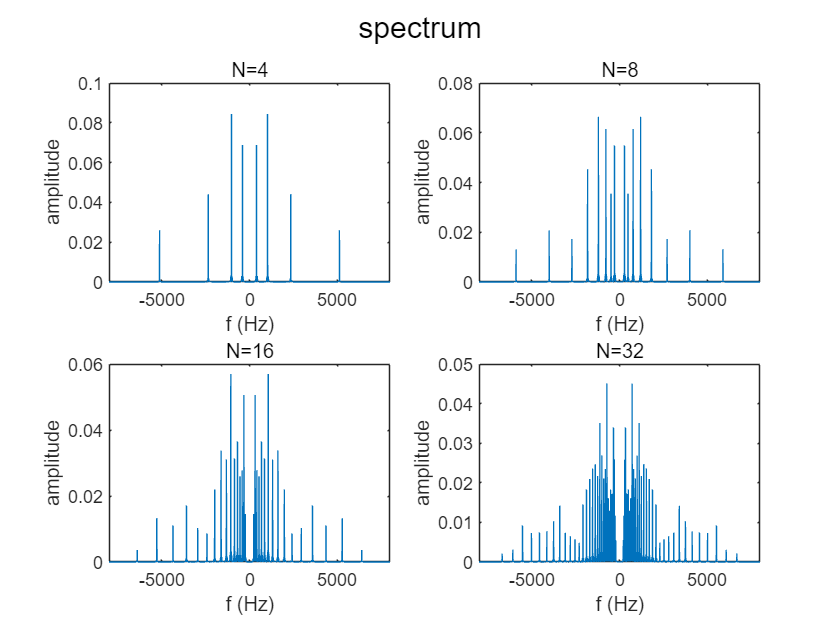


if mod(length(sig), 2) == 1
    freqency = linspace(-fs/2, fs/2, length(sig));
else
    freqency = linspace(-fs/2, fs/2, length(sig) + 1);
    freqency = freqency(1:end-1);
end
figure;
sgtitle('spectrum');
subplot(2, 2, 1);
plot(freqency, abs(fftshift(fft(N_4))/fs));
axis([freqency(1) freqency(end) ylim]);
title('N=4');
xlabel('f (Hz)');
ylabel('amplitude');
subplot(2, 2, 2);
plot(freqency, abs(fftshift(fft(N_8))/fs));
axis([freqency(1) freqency(end) ylim]);
title('N=8');
xlabel('f (Hz)');
ylabel('amplitude');
subplot(2, 2, 3);
plot(freqency, abs(fftshift(fft(N_16))/fs));
axis([freqency(1) freqency(end) ylim]);
title('N=16');
xlabel('f (Hz)');
ylabel('amplitude');
subplot(2, 2, 4);
plot(freqency, abs(fftshift(fft(N_32))/fs));
axis([freqency(1) freqency(end) ylim]);
title('N=32');
xlabel('f (Hz)');
ylabel('amplitude');

Save the processed audio.

audiowrite('proj1/T3_4_50.wav', N_4, fs);
audiowrite('proj1/T3_8_50.wav', N_8, fs);
audiowrite('proj1/T3_16_50.wav', N_16, fs);
audiowrite('proj1/T3_32_50.wav', N_32, fs);

#### Destcription

### Task 4

- Generate a noisy signal (summing clean sentence and SSN) at SNR -5 dB.

- Set the number of bands to N=8.

- Implement tone-vocoder by changing the LPF cut-off frequency to 20 Hz, 50 Hz, 100 Hz, and 400 Hz.

- Describe how the LPF cut-off frequency affects the intelligibility of synthesized sentence.

Initialize and load audio.

clear;clc;
[sig, fs] = audioread('proj1/C_01_02.wav');

Generate -5 dB SNR.

snr = sig / sqrt(10);

Generate speech-shaped noise (SSN).

ssn = get_ssn(snr, fs) .* 10^(1/4);

Generate noisy signal.

noisy_sig = sig + ssn;

 Check SNR -5 dB.

feq(20 * log10(norm(sig)/norm(ssn)), -5)

ans = logical
   1


Set the number of bands.

N = 8;

Implement tone-vocoder.

cut_off = 20 (Hz)

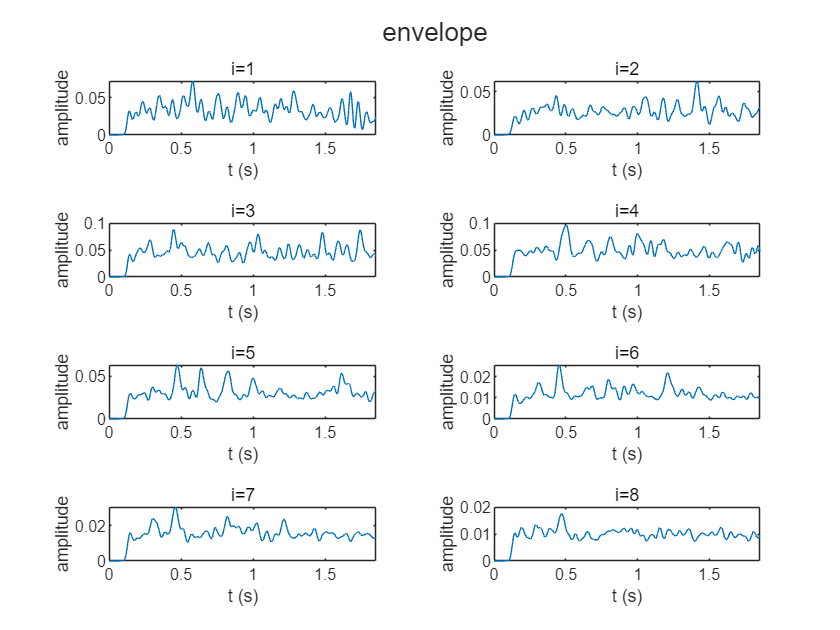

cut_off_20 = speech_synthesis(noisy_sig, fs, N, 20);

cut_off = 50 (Hz)

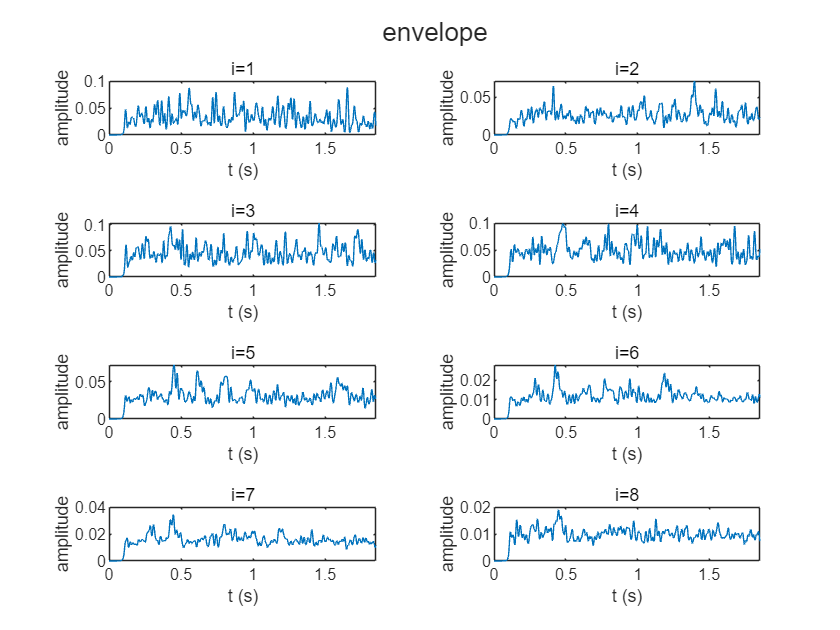

cut_off_50 = speech_synthesis(noisy_sig, fs, N, 50);

cut_off = 100 (Hz)

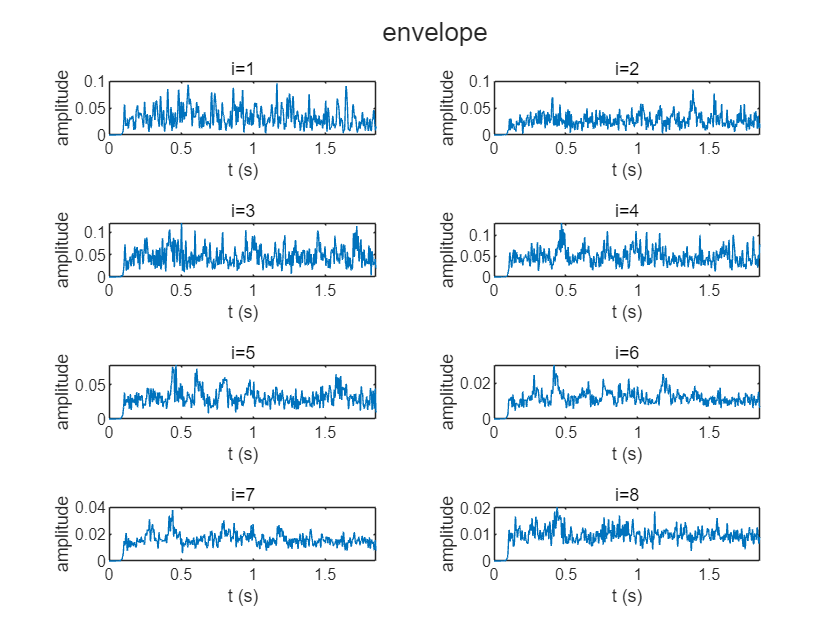

cut_off_100 = speech_synthesis(noisy_sig, fs, N, 100);

cut_off = 400 (Hz)

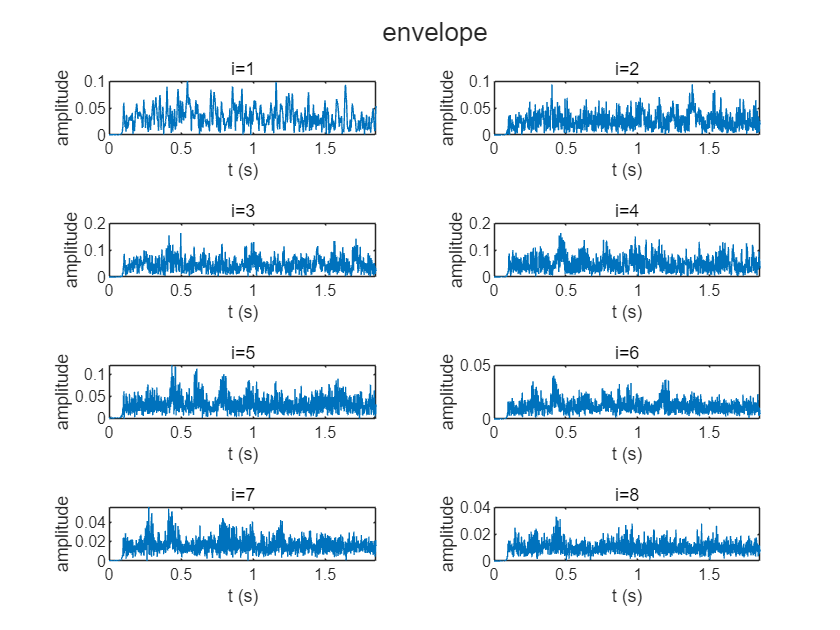

cut_off_400 = speech_synthesis(noisy_sig, fs, N, 400);

Check energy normalization.

noisy_sig_norm = norm(noisy_sig);
feq(norm(cut_off_20), noisy_sig_norm)

ans = logical
   1


feq(norm(cut_off_50), noisy_sig_norm)

ans = logical
   1


feq(norm(cut_off_100), noisy_sig_norm)

ans = logical
   1


feq(norm(cut_off_400), noisy_sig_norm)

ans = logical
   1


Plot each result.

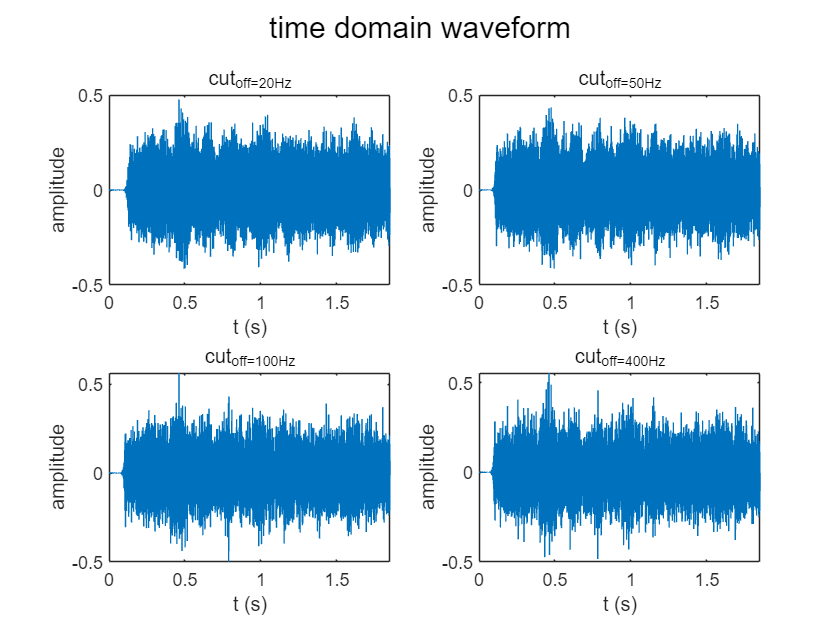

t = (0:length(sig)-1)'./fs;
figure;
sgtitle('time domain waveform');
subplot(2, 2, 1);
plot(t, cut_off_20);
axis([t(1) t(end) ylim]);
title('cut_off=20Hz');
xlabel('t (s)');
ylabel('amplitude');
subplot(2, 2, 2);
plot(t, cut_off_50);
axis([t(1) t(end) ylim]);
title('cut_off=50Hz');
xlabel('t (s)');
ylabel('amplitude');
subplot(2, 2, 3);
plot(t, cut_off_100);
axis([t(1) t(end) ylim]);
title('cut_off=100Hz');
xlabel('t (s)');
ylabel('amplitude');
subplot(2, 2, 4);
plot(t, cut_off_400);
axis([t(1) t(end) ylim]);
title('cut_off=400Hz');
xlabel('t (s)');
ylabel('amplitude');

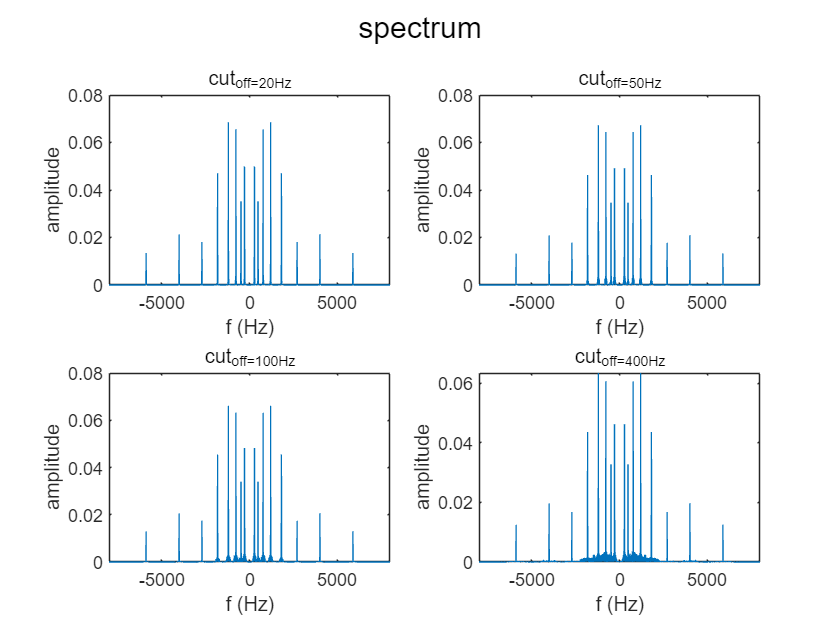


if mod(length(sig), 2) == 1
    freqency = linspace(-fs/2, fs/2, length(sig));
else
    freqency = linspace(-fs/2, fs/2, length(sig) + 1);
    freqency = freqency(1:end-1);
end
figure;
sgtitle('spectrum');
subplot(2, 2, 1);
plot(freqency, abs(fftshift(fft(cut_off_20))/fs));
axis([freqency(1) freqency(end) ylim]);
title('cut_off=20Hz');
xlabel('f (Hz)');
ylabel('amplitude');
subplot(2, 2, 2);
plot(freqency, abs(fftshift(fft(cut_off_50))/fs));
axis([freqency(1) freqency(end) ylim]);
title('cut_off=50Hz');
xlabel('f (Hz)');
ylabel('amplitude');
subplot(2, 2, 3);
plot(freqency, abs(fftshift(fft(cut_off_100))/fs));
axis([freqency(1) freqency(end) ylim]);
title('cut_off=100Hz');
xlabel('f (Hz)');
ylabel('amplitude');
subplot(2, 2, 4);
plot(freqency, abs(fftshift(fft(cut_off_400))/fs));
axis([freqency(1) freqency(end) ylim]);
title('cut_off=400Hz');
xlabel('f (Hz)');
ylabel('amplitude');

Save the processed audio.

audiowrite('proj1/T4_8_20.wav', cut_off_20, fs);
audiowrite('proj1/T4_8_50.wav', cut_off_50, fs);
audiowrite('proj1/T4_8_100.wav', cut_off_100, fs);
audiowrite('proj1/T4_8_400.wav', cut_off_400, fs);

#### Destcription

### Functions

The function to judge two floating point number equal.

(Since floating point number comparison exists precision problem, when the difference between two floating point number is smaller than a very small value $\epsilon$, we think they're the same)

(The precision problem will be magnified after complex calculation, so instead of using the $eps$ in matlab, we loose the judging criteria and use a bigger $\epsilon$)

function res = feq(a, b)
    res = abs(a-b) < 1e-12;
end

The function to get the corresponding cochlea length (in $mm$) from a certain frequency (in $Hz$).

function d = freq2cochlea (f)
    d = log10(f./165.4 + 1) ./ 0.06;
end

The function to get the corresponding frequency (in $Hz$) from a certain cochlea length (in $mm$).

function f = cochlea2freq (d)
    f = 165.4 .* (10.^(0.06.*d) - 1);
end

The function to get the frequency (in $Hz$) equally divided by the cochlea length.

function f = divide_freq (n)
persistent d0 d1;
if isempty(d0)
    d0 = freq2cochlea(200);
    d1 = freq2cochlea(7000);
end
f = cochlea2freq(linspace(d0, d1, n + 1));
end

The function to get figure objects can contain given number of figure.

function figure_obj = get_figures(N, title, each_figure_num)
    if nargin < 3
        each_figure_num = 16;
        if nargin < 2
            title = '';
        end
    end

    figure_num = ceil(N/each_figure_num);
    figure_obj = gobjects(figure_num, 1);
    for i = 1:figure_num-1
        figure_obj(i) = figure();
        tiledlayout(4, 4);
        sgtitle(title);
    end
    last_figure_num = N - (figure_num-1) * each_figure_num;
    if last_figure_num == 0
        last_figure_num = each_figure_num;
    end
    last_figure_col = floor(sqrt(last_figure_num));
    last_figure_row = ceil(last_figure_num/last_figure_col);
    figure_obj(figure_num) = figure();
    tiledlayout(last_figure_row, last_figure_col);
    sgtitle(title);
end

The speech synthesis function.

function res = speech_synthesis(s, fs, N, cut_off, band_order, low_order)
if nargin < 5
    band_order = 4;
    low_order = 6;
end
% prepare the figure
band_figure = get_figures(N, 'frequency responese of band\_pass filter');
low_figure = get_figures(N, 'frequency responese of low\_pass filter');
envelope_figure = get_figures(N, 'envelope');
% initialize res and t
res = zeros(length(s), 1);
t = (0:length(s)-1)'./fs;
% get the band edge's frequency
f = divide_freq(N);
% for each band
for i = 2:length(f)
    lower = f(i-1);
    higher = f(i);
    % design band-pass filter
    [b,a] = butter(band_order, [lower higher]/(fs/2));
    % calculate and plot the frequency response of the band-pass filter
    [H, omega] = freqz(b,a);
    frequency = omega * (fs/(2*pi));
    figure(band_figure(ceil((i-1)/16)));
    nexttile;
    plot(frequency, abs(H));
    axis([frequency(1) frequency(end) ylim]);
    xlabel('f (Hz)');
    ylabel('H(j\omega)');
    title(['i=' num2str(i-1)])
    % do band-pass filtering
    y = filter(b, a, s);
    % do full-wave rectification
    y = abs(y);
    % design low-pass filtering
    [b,a] = butter(low_order, cut_off/(fs/2));
    % calculate and plot the frequency response of the low-pass filter
    [H, omega] = freqz(b,a);
    frequency = omega * (fs/(2*pi));
    figure(low_figure(ceil((i-1)/16)));
    nexttile;
    plot(frequency, abs(H));
    axis([frequency(1) frequency(end) ylim]);
    xlabel('f (Hz)');
    ylabel('H(j\omega)');
    title(['i=' num2str(i-1)])
    % do low-pass filtering
    y = filter(b, a, y);
    % calculate and plot the envelope
    figure(envelope_figure(ceil((i-1)/16)));
    nexttile;
    plot(t, y);
    axis([t(1) t(end) ylim]);
    xlabel('t (s)');
    ylabel('amplitude');
    title(['i=' num2str(i-1)])
    % generate sinewave
    sinwave = sin((2*pi*(lower+higher)/2) .* t);
    % multiple the sinwave
    y = sinwave .* y;
    % add to the result
    res = res + y;
end
% do energy normalization
res = res .* (norm(s)/norm(res));
end

The function to generate speed-shaped noise (SSN) with the same energy.

function ssn = get_ssn(sig, fs)
if iscolumn(sig)
    % generate white noise
    whitenoise = 1 - 2*rand(length(sig),1);
    % generate long-term spectrum of speech signal to estimate the power spectral density of the speech signal
    sig = repmat(sig, 10, 1);
else
    % generate white noise
    whitenoise = 1 - 2*rand(1,length(sig));
    % generate long-term spectrum of speech signal to estimate the power spectral density of the speech signal
    sig = repmat(sig, 1, 10);
end
[Pxx,f] =pwelch(sig, [], [], 512, fs);
% generate filter coefficients
b = fir2(3000, f / (fs/2), sqrt(Pxx/max(Pxx)));
% perform filtering for white noise signal to get the SSN
ssn = filter(b, 1, whitenoise);
% do energy normalization
ssn = ssn .* (norm(sig)/norm(ssn));
end

### Summary

## Expeience

........................